# Tasks 5

## Preparing the MerchData image dataset

We'll work with the MerchData dataset again. Load the MerchData dataset as an `imageDatastore` using the foldernames as class labels. Divide your `imageDatastore` object into two smaller `imageDatastore` objects, one containing a random 60% of the images in each class for use in training, and one containing the remaining 40% of the images in each class for use in testing:

(**Sanity check**: you have completed these exact same steps before, check over your previous work if you're struggling, or ask for help)

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

imds = imageDatastore('MerchData','IncludeSubfolders', true,'LabelSource','foldernames');
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');



## Maximum rate of increase

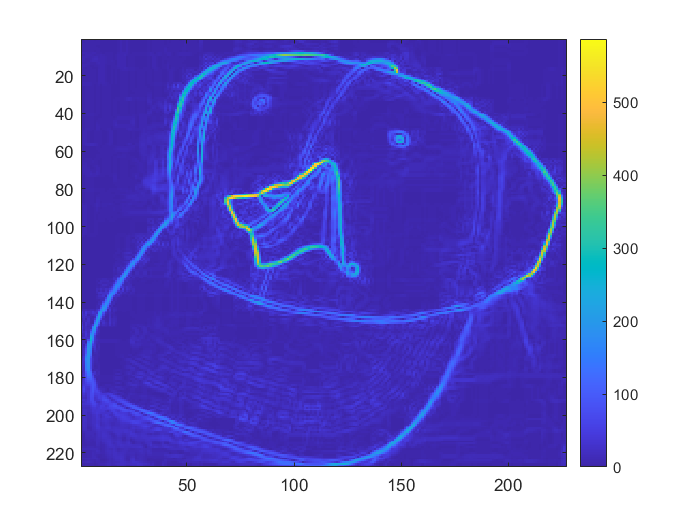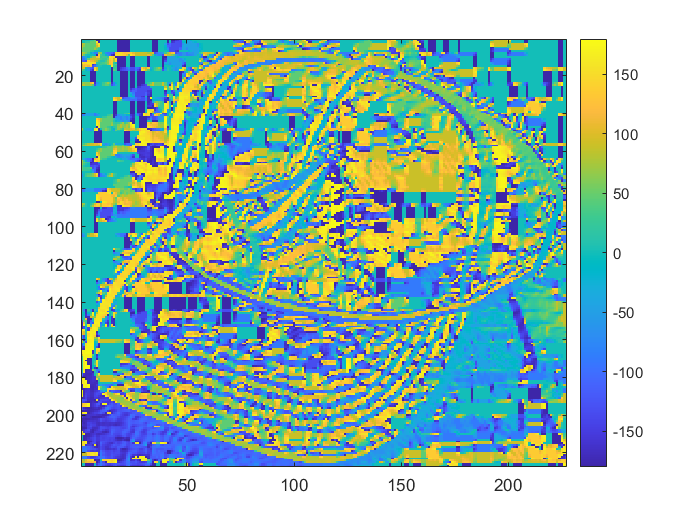

We've previously worked on finding vertical and horizontal gradients in the image, separately. Here we're interested in local gradients in general, no matter what orientation they have, and we'll shift to working with *maximum rate of increase* information at each pixel. Matlab's built-in `imgradient()` function can do this calculation for you, accepting the two arrays outputted by `imgradientxy()` as its input and outputting two further arrays giving the *magnitude* and the *direction* of the maximum rate of increase at every point in your image.

Load the first image from your training `imageDatastore` and convert it to greyscale. Next, take the necessary steps to make a call to `imgradient()` and then generate two visualisations from the results: the first showing the local gradient *magnitudes*; and the second showing the local gradient *direction*:

(**Sanity check**: the visualisation of directions -- which can be anywhere from -180 to +180 degrees -- can look a little odd, don't worry; you should get results similar to the images above, depending on your exact approach to visualisation)

% im = training.readimage(1);
% im = im2gray(im);
% [Gx,Gy] = imgradientxy(im,'prewitt');
% 
% [mag,dir] = imgradient(Gx,Gy);
% imagesc(mag);
% imagesc(dir);


## HOG features I

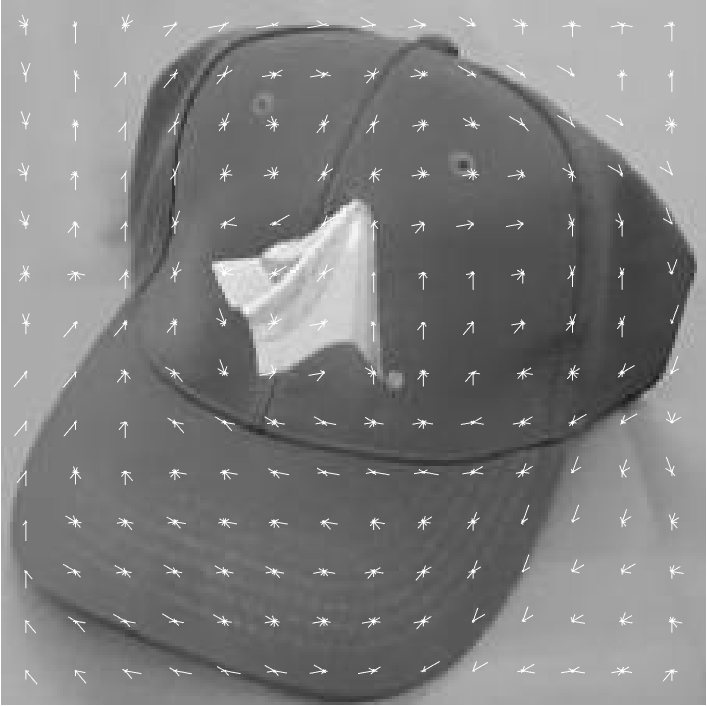

Histograms of oriented gradient (HOG) features calculate exactly the same *maximum rate of increase* magnitudes and directions that you calculated in the previous task, and then aggregate local gradient information over small patches within the image by constructing a histogram.

Load the first image from your training `imageDatastore` and convert it to greyscale. Next use the `extractHOGFeatures()` function to extract HOG features from it with a patch size of 16*16 pixels, and generate a rose plot visualisation of the results:

(**Sanity check**: you should get something very close to the image above)

% CELLSIZE = [16 16];
% [h,v] = extractHOGFeatures(im,'CellSize',CELLSIZE,'BlockSize', [floor(size(im,1)/CELLSIZE(1)) floor(size(im,2)/CELLSIZE(2))],'UseSignedOrientation', true);
% 
% imshow(im);

%hold('on');
%v.plot();



## Histogram bin totals for a single image

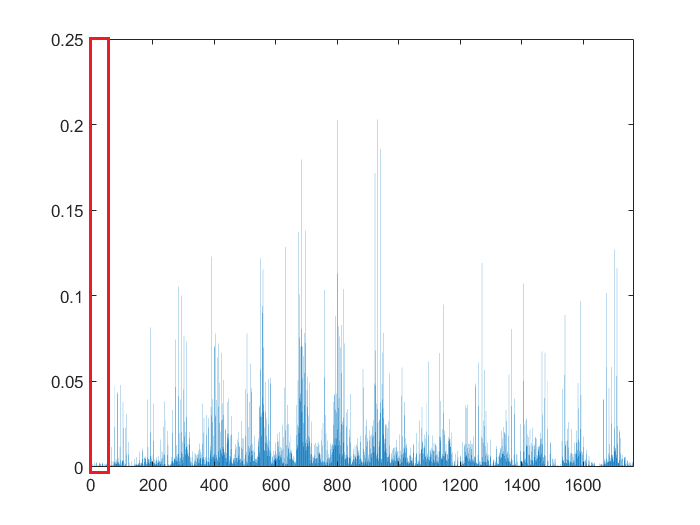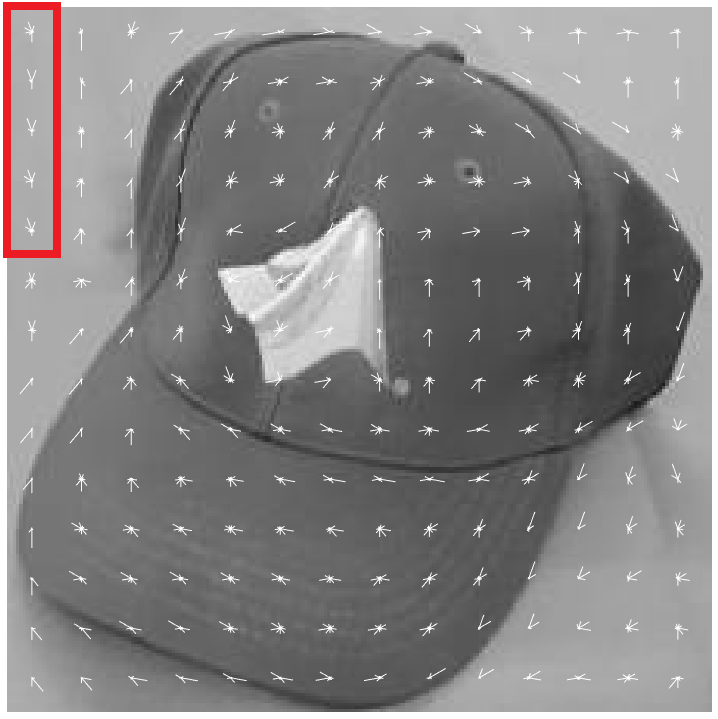

The rose plot visualisation we generate above can be a little misleading as the spike or "petal" representing each bin has its length set based on the *relative* contribution that bin makes to the histogram in that patch. I.e., the histograms are "standardised", and the total length of all petals in each rose plot will sum to a constant. In actual fact the sizes of the histograms in different patches can be very different. Those patches that contain only very small local gradients (e.g., patches on the untextured background behind the hat) have only very small totals in each bin. Whereas patches that lie over strong local gradients (e.g., the edge of the badge on the front of the hat) have very large bin sizes in at least some directions. You can get a sense of just how much variation there is in the magnitudes of different patches by just plotting them out. 

Add some code below to open a new figure and plot out all the features you got back from the image as a bar graph:

(**Sanity check**: you really do need to open a new figure first if you turned hold on when generating the rose plot in the previous task)

(**Sanity check**: You should get something very close to the image above. Every chunk of 9 numbers across the x-axis represents a single histogram for one patch. Notice that some histograms are much smaller than others. E.g., the first 45 numbers (from x=0 to around x=50 on the x-axis) are the 5 background patches in the top left hand column of the image, all with very small bin totals (as there are almost no local gradients).)

% f = figure;
% figure(f);
% bar(h);



## HOG features II

Now reuse your code from the earlier task to extend the `get_hogs()` function stub so that for any image passed in, it converts it to greyscale, then extracts HOG features using a patch size of 16*16 pixels, and returns the resulting array of histogram bin totals. Add code below to pass the first image in your training `imageDatastore` to your new function and convince yourself that it returns the correct answer:

(**Sanity check**: you should be able to use the array returned by your new function to recreate the bar graph you plotted in the previous task)

%t = get_hogs(im);
%plot(t)
%bar(t);


## Extract training data

The `Labels` property of your training `imageDatastore` contains the class labels for each of your training images, in order. Copy it into a variable called `train_labels`. Now by looping over the images in your training `imageDatastore`, and calling your `get_hogs()` function with each one, construct an array of corresponding HOG features called `train_examples`. If you're struggling, consider checking the Matlab fundamentals for a reminder of how you can grow arrays downwards, checking the reusable code in the lecture slides, or having a play around in the Command Window to remind yourself:

(**Sanity check**: `train_examples` should be a 2D array, where each row contains all the histograms for a single training image (so it should have the same height as `train_labels` and a width equal to the total number of histogram bins) - call `size()` on it to check; if you get something with fewer elements consider whether you need to call `reset()` on your training `imageDatastore`)

train_labels = training.Labels;
train_examples =[];

while hasdata(training)
    im = im2gray(training.read());
    train_examples(end+1,:) = get_hogs(im);
end



## Train and evaluate an image classifier

Use the `train_examples` and `train_labels` arrays you created in the previous task to call `fitcknn()` and train a k-NN classifier with k=3 neighbours. Next, build `test_examples` and `test_labels` arrays from your testing data in just the same way you did for the previous task, and use these new arrays to evaluate your classifier's performance by computing a confusion matrix and overall classification accuracy.

(**Sanity check**: you should expect a small performance improvement on the edge-based approach from the previous task sheet: 63.3%)

(**Sanity check**: performance with HOG features on the MerchData is never likely to be *really* good. The imaging conditions for the MerchData aren't tightly constrained (images feature different viewpoints/scales/rotations) and so the objects in the images don't always appear in the same positions and neither do the resulting HOG features. However, two things to note: i) in the next set of lab tasks we'll relax the assumption that HOG features have to appear in a particular location and get better performance; ii) many problems do have tightly constrained imaging conditions - if you'd like to see some good performance with HOG features then try the face identity classification problem in the later extension tasks...)

test_labels = testing.Labels;
test_examples =[];

while hasdata(testing)
    im = im2gray(testing.read());
    test_examples(end+1,:) = get_hogs(im);
end

kNN = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, test_examples);

[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 56.6667

## Extension task: calculating the maximum rate of increase

This task is about coding up the *maximum rate of increase* calculations done by the built-in `imgradient()` function. Have a look at the `my_imgradient()` stub and extend it to return maximum rate of increase information (magnitude and angle) at every pixel. You can call your `my_imgradientxy()` function from the earlier extension exercise to generate the function's two inputs - an array of all the vertical gradients in the image and another of all the horizontal gradients in the image. (Or you can make a call to the built-in `imgradientxy()` function if you haven't completed that extension task yet, or you're not confident in your solution.) 

Remember, you can then treat the two gradients at each pixel as sides of a right-angled triangle and compute an overall direction and magnitude from them using some simple trigonometry (see the lectures for extra guidance)

Add some code below to recreate the local gradient *magnitude* and *direction* visualisations that you produced in the earlier task:

(**Hint**: remember you can use the `atan2()` function to simplify the job of calculating the *directions* - see the lectures slides for further guidance)

%im = training.readimage(1);
%im = im2gray(im);
%get_hogs(im)


% 
% [Gx, Gy] = imgradientxy(im);
% 
% [Gmag, Gdir] = imgradient(Gx,Gy);
% 
% rad = atan2(-Gy, Gx);
% maxRate = rad * 180/pi;




## Extension task: standardisation

As we saw in the previous task, different HOG features can have very different sizes or magnitudes. However, the HOG extraction algorithm does take steps to standardise the magnitudes of histogram bins across the image - the idea being that while the relative sizes of the HOG features can be very useful, their absolute sizes are conditional on lighting. E.g., a brighter light tends to increase the gradient between surfaces that do and don't reflect light back to the camera, and it would be nice to have some insensitivity to this effect.

In the particular way in which we call it, the HOG extraction algorithm standardises *all* histograms right across the whole image in a single step. There are lots of possible approaches to performing standardisation (you may have read about some if you did the further reading for the k-NN classifier). But the approach taken by the HOG extraction algorithm is to require that the collection of bin totals resulting from a given image has an *L2 norm* equal to 1.

In practice, this means that the extraction algorithm treats the bin totals from an image as defining a single point in a high-dimensional space, and then shifts that point back in a direct line towards the origin until the Euclidean distance between the point and the origin is 1.

Write a simple expression to find the distance between a point at a coordinate defined by the list of histogram bin totals resulting from the first image from your training `imageDatastore`, and the origin.

(**Hint**: you might need to look back at the lecture slides on k-NN for a reminder of how to calculate Euclidean distance; but you might also have already written a useful function to do it for you if you completed the extension exercises)

(**Hint**: if you are implementing the equation for the first time then note that as the coordinates of the origin are all zeros, the first subtraction step isn't actually required)

% %reset(training);
% im = training.readimage(1);
% im = im2gray(im);
% 
% hist = -180:40:140;
% im = im2gray(im);
% 
% [Gx, Gy] = imgradientxy(im,'prewitt');
% [Gmag, Gdir] = imgradient(Gx,Gy);
% 
% 
% bin = zeros(196,9);
% 
% row = 0;
% 
% 
% %test = cat(3,Gdir,Gmag);
% 
% 
% 
% %increments over a 16*16 patch for HOG extraction
% for i=0:16:size(Gdir,1)
%     for j=0:16:size(Gdir,2)
% 
%         if (i < 1)
%             i = i+1;
%         end
%         if (j < 1)
%             j = j+1;
%         end
% 
%         %error checking to see if its in the bounds of the array
%         if(j+16 <= size(Gdir,1) && i+16 <= size(Gdir,1) || j <= size(Gdir,1) && i <= size(Gdir,1))
%             dirPatch = Gdir(i:i+15,j:j+15);
%             magPatch = Gmag(i:i+15,j:j+15);
%             row = row +1;
%             if(j <= size(Gdir,1) && i <= size(Gdir,1))
%                 r = size(Gdir,1) - i;
%                 dirPatch = Gdir(i:r,j:r);
%                 magPatch = Gmag(i:r,j:r);
%         
%         
% 
% 
%         for l=1:1:size(dirPatch,1)
%             for m=1:1:size(dirPatch,2)
% 
% 
%                 dir= dirPatch(l,m);
%                 %creates a patch sample of the image
% 
%                 %loops over 9 bins for sampling of the data
%                 for k=-180:40:140
% 
% 
% 
%                     if(dir >= k) && (dir < k+40)
%                         col = find(hist==k,1);
%                         mag = magPatch(l,m);
% 
%                         prev = bin(row,col);
%                         cur = prev+mag;
% 
%                         bin(row,col) = cur;
% 
%                     end
% 
%                 end
% 
%             end
%         end
% 
% 
%        
% 
%             end
%         end
%     end
% end
% 
% 
% bin;
% h = reshape(bin',1,numel(bin)) ;
% 
% k = sqrt( sum( abs(h) .^ 2 ) );
% 
% h = h / k
% 







% t = get_hogs(im);
% sum(t)
% max(t)
% min(t)
% avg = sum(t) / numel(t);
% avg

%class(t)
%bar(t)

## Extension task: implementing histograms of oriented gradients calculation

This task is about coding up the HOG feature extraction for yourself. Try implementing the `my_extractHOGFeatures()` function stub so that for any greyscale image passed in, it extracts *maximum rate of increase* information, processes it in 16*16-pixel patches by using individual directions and magnitudes to construct histograms (each with 9 bins), and standardises those histograms using unit L2 norm. There are quite a few steps to remember in your implementation, and the bullet points below take you through the important stages from the lecture. We won't get *exactly* the same feature values out as the built-in `extractHOGFeatures()` function -- it performs some extra smaller steps that are beyond our scope -- but we'll get information that is essentially the same, and you can expect a very similar classification accuracy (see the sanity check below):

- The first job is to convert the image to grayscale and extract the *maximum rate of increase* vectors at every pixel. You can call your own `my_imgradientxy()` and `my_imgradient()` functions in order to do this but perhaps start off with calls to the built-in equivalents as a precaution (or if you haven't yet completed the earlier extension exercises)

- You need to process the results in 16*16 pixel patches. Nested for loops are almost certainly the way to go because we need to do extra processing within each patch; build yourself a nested for loop that jumps across the results from `imgradient()` with the appropriate jump sizes (careful, it's easy to get the jump sizes slightly wrong - perhaps practice generating the arrays at the Command Window)

- Try adding code to construct the basic histogram for each block. For each of the 16*16 different gradient directions in each block, you need to find their closest histogram bin - you can do this however you like (as long as you code it for yourself, rather than relying on another built-in function), but there is a suggested approach included in the function stub if you want some guidance

- You can use a call to the built-in `zeros()` function to initialise each new histogram with all bins set to zero. But remember that we add the *magnitude* of each local gradient to its nearest histogram bin (not just simply a +1)

- As you generate your histograms for an image, you simply need to concatenate them together side-by-side in a long horizontal 1D array ready to pass back to the caller (and you know how to use []-notation to concatenate arrays; check the Matlab fundamentals if not)

- Once you have all your histograms, standardising them just requires you to make sure the resulting vector has unit length (a length of 1); this involves calculating its initial length and then dividing all its coordinates by the result (you can also draw on your work in the previous task on standardisation)

Once your implementation is ready, substitute the call to `getHOGFeatures()` in your `get_hogs()` function for a call to your new `my_getHOGFeatures()` function and re-run this entire script to see how your classification accuracy in the earlier task changes.

(**Sanity check**: you should get exactly the same number of histograms/features per image as you did with the built-in `extractHOGFeatures()` function - make sure this is the case with some suitable calls to `size()` before you worry about anything else)

(**Sanity check**: call your finished `my_extractHOGFeature()` function on the first image in your training dataset and plot all the values that come back in a bar graph; does what you see make sense?)

(**Sanity check**: you should get the same performance -- an overall accuracy of 63.3% -- when calling `my_extractHOGFeatures()` rather than `extractHOGFeatures()`. The functions aren't identical, and we might get different performances using different splits of the data or HOG/classifier parameters, but the two implementations are very similar and the same on all the big issues)

## Extension task (optional): face classification

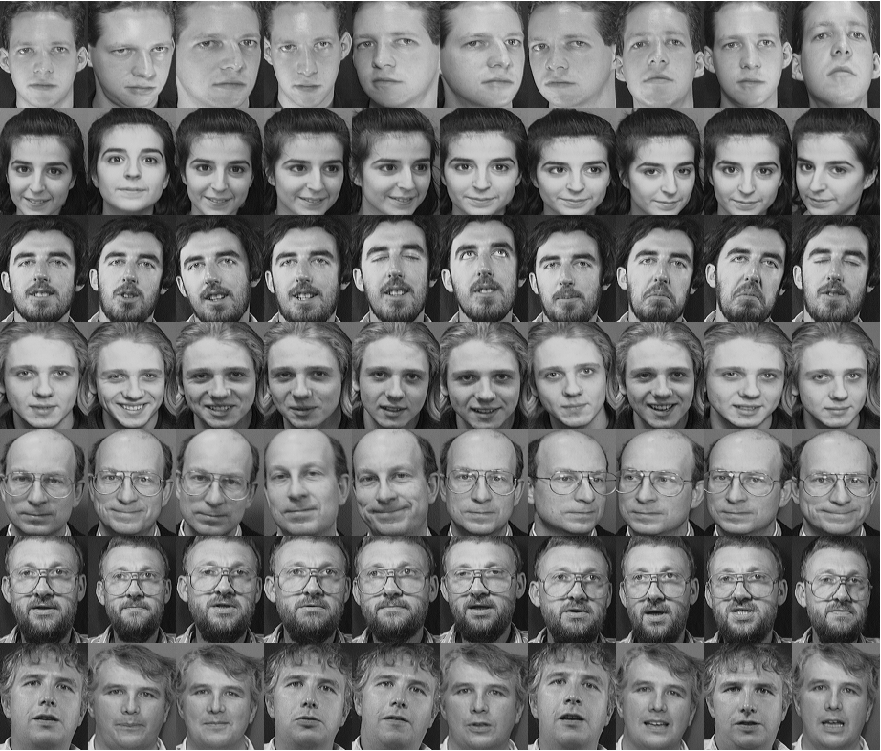

[**Note: this task isn't directly relevant to 1CWK50 - it's just here for interest, and to show another application of classification with HOG features; feel free to skip it if you want to**]

The FaceDatabaseATT dataset contains images of different people's faces. The images obey a quite tight set of constraints (same size, tightly cropped, consistent lighting, consistent viewpoint, etc.) and are suitable for use in an identity classification problem where we directly compare HOG features between different images (i.e., we expect, broadly speaking, that the same parts of different faces will lie in the same particular sub-regions of the images; see the lecture slides for more discussion). Load the database up, split it, and use it to train and evaluate a classifier based on HOG features extracted from patches of size of 8*8 pixels:

(**Sanity check**: it shouldn't be too difficult to get performance up above 80% regardless of choice of classifier/hyperparameters)

You need to download digits.zip from Moodle and unzip it into the same directory as this live script

## Extension task (optional): digit classification

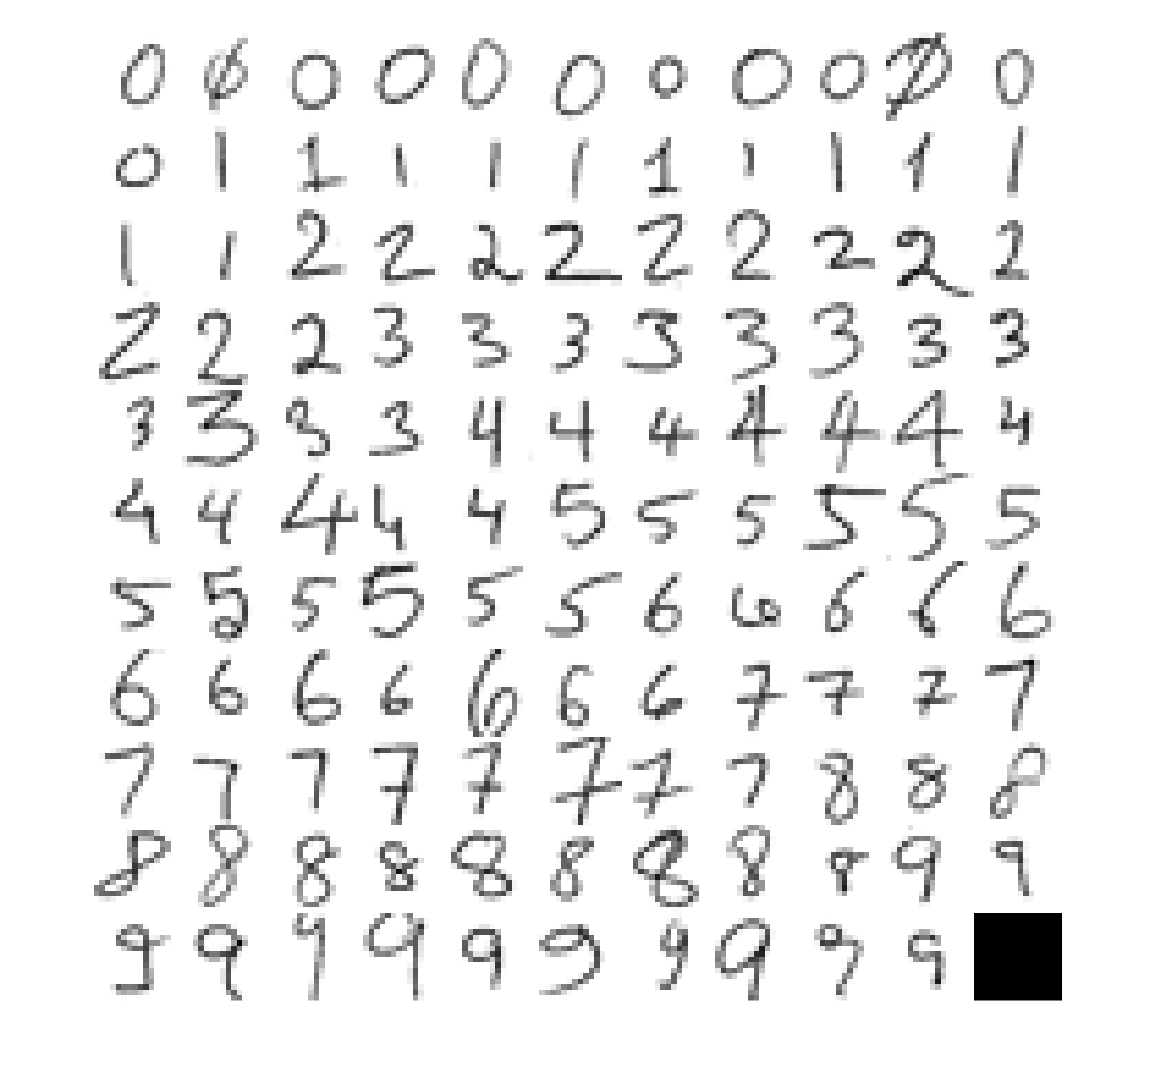

[**Note: this task isn't directly relevant to 1CWK50 - it's just here for interest, and to show another application of classification; feel free to skip it if you want to**]

The digits dataset contains two folders of images showing handwritten digits. In fact one folder (/synthetic/) contains images that don't actually show real handwriting, but have instead been created using a word processing program (like Word). This dataset is particularly interesting as it lets you see if you can classify the real hand-written digits (in the /handwritten/ folder) by training only on the synthetic digits. More generally, synthesising large amounts of "fake" (but still useful) training data is a really interesting approach in AI (see for example how the original Microsoft Kinect's ML algorithm was trained in the original paper: [here](https://www.microsoft.com/en-us/research/wp-content/uploads/2016/02/BodyPartRecognition.pdf)). Load the database up, using the /synthetic/ folder to create a training `imageDatastore` and the /handwritten/ folder to create a testing `imageDatastore`, then see what kind of classification performance you can get using HOG features. You will probably want a relatively small patch size as the images are quite small:

(**Sanity check**: this dataset is more challenging due to the natural variations in people's handwriting styles, and lower classification accuracies are likely (perhaps around 55-60% depending on classifier/hyperparameters). But we'll see how to get all the way up to 98%, 99% and even 100% with the techniques we meet in the remainder of the unit...)

% check the dataset is present:
if ~exist('./digits', 'dir')
    error('You need to download digits.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

% write your code on the lines below:

